# GeoPlotWaves 

Author: M. Noyce

This program takes the processed wave height and wave period time series from TimeAnalysisAllSeries.mlx, cross references their times with the logged GPS times for each buoy and plot them on a geographic map. Program starts by extracting raw geographic data 

## Import Raw Geographical Data 

projectdir = "C:\Users\uctsh\Documents\MATLAB\GPSData\";


## SB04 GPS and Wave Parameter Preprocessing

gpsfileSB04 = fullfile(projectdir, "SB04_GPS_Local.txt"); 
%GPS Data
SB04 = readtable(gpsfileSB04);
Device = 4*ones(height(SB04), 1); 
SB04 = addvars(SB04, Device, 'before', "TimeUTC"); 
%Filter out null GPS values
SB04 = SB04(SB04.("Latitude") < 0.0, :);

%Wave Parameters 
waveParamSB04 = readtable("SB04_Wave_Parameters_Heave.txt");
%Note 17:09 20/07/2022 was defined as sample no 1

%Add sample no. to wave parameters
waveParamSB04.sampleNo = (1:height(waveParamSB04)).'

waveParamSB04 = 127×6 table
        DateTimeUTC           Hm0       Tm01     Hm0_upper    Hm0_lower    sampleNo
    ____________________    _______    ______    _________    _________    ________

    20-Jul-2022 15:45:08     12.361    49.695      16.782       9.8638         1   
    20-Jul-2022 16:27:02    0.34254    17.718     0.46504      0.27333         2   
    20-Jul-2022 17:09:05    0.35314    17.173     0.47944      0.28179         3   
    20-Jul-2022 17:51:08    0.37906    16.741     0.51462      0.30247         4   
    20-Jul-2022 18:33:04    0.41966    17.381     0.56975      0.33487         5   
    20-Jul-2022 19:15:07    0.50186    17.426     0.68135      0.40046         6   
    20-Jul-2022 19:57:09    0.53462    17.056     0.72582       0.4266         7   
    20-Jul-


%Remove all null wave parameters
waveParamSB04 = rmmissing(waveParamSB04);

%Remove all samples before sample no 1
SB04 = SB04(SB04.DateTimeUTC > datetime(2022, 07, 20, 15, 40, 00), :);
SB04 = SB04(SB04.DateTimeUTC < datetime(2022, 07, 24, 07, 50, 00), :)

SB04 = 252×16 table
        DateTimeUTC         timeSeriesCount    Device            TimeUTC            Latitude    Longitude       Time       HDOP_Digit    HDOP_Precision    PDOP_Digit    PDOP_Precision    VDOP_Digit    VDOP_Precision    Num_Satellites    FixType    ExtraVar1 
    ____________________    _______________    ______    _______________________    ________    _________    __________    __________    ______________    __________    ______________    __________    ______________    _


%Create array of interpolated GPS Data (midpoint method ) TODO: More
%advanced method

GPSinter = zeros( ceil(height(SB04)/2), 2);
j = 1; %inner loop counter

for i = 2 : height(SB04)
    if SB04.timeSeriesCount(i) ==  SB04.timeSeriesCount(i-1)
        GPSinter(j, 1) = (SB04.Latitude(i) + SB04.Latitude(i - 1))/2; 
        GPSinter(j, 2) = (SB04.Longitude(i) + SB04.Longitude(i - 1))/2;
        j = j +1; 
    end
end

%if uneven sampling sessions
if (GPSinter(end, 1) == 0)
    GPSinter(end, :) = [];
end


%Add interpolated values to wave parameter table:
waveParamSB04 = addvars(waveParamSB04, GPSinter(:, 1), GPSinter(:, 2), 'NewVariableNames', {'Latitude','Longitude'}); 
waveParamSB04 = convertvars(waveParamSB04,{'Latitude','Longitude'},'double');

## SB06 GPS and Wave Parameter Preprocessing

gpsfileSB06 = fullfile(projectdir, "SB06_GPS_Local.txt"); 
%GPS Data
SB06 = readtable(gpsfileSB06);
Device = 6*ones(height(SB06), 1); 
SB06 = addvars(SB06, Device, 'before', "TimeUTC"); 
%Filter out null GPS values
SB06 = SB06(SB06.("Latitude") < 0.0, :);

%Wave Parameters 
waveParamSB06 = readtable("SB06_Wave_Parameters_Heave.txt");
%Note 17:09 20/07/2022 was defined as sample no 1

%Add sample no. to wave parameters
waveParamSB06.sampleNo = (1:height(waveParamSB06)).'

waveParamSB06 = 90×6 table
        DateTimeUTC           Hm0       Tm01     Hm0_upper    Hm0_lower    sampleNo
    ____________________    _______    ______    _________    _________    ________

    20-Jul-2022 19:28:23    0.42397    18.095      0.5756      0.33831         1   
    20-Jul-2022 20:10:03    0.48091    18.255      0.6529      0.38374         2   
    20-Jul-2022 20:51:42    0.50613    17.989     0.68715      0.40387         3   
    20-Jul-2022 21:33:14    0.64694    17.766     0.87831      0.51623         4   
    20-Jul-2022 22:14:53    0.62541    17.215     0.84908      0.49905         5   
    20-Jul-2022 22:56:32    0.75917    17.351      1.0307      0.60579         6   
    20-Jul-2022 23:38:02    0.63653    17.243     0.86418      0.50792         7   
    21-Jul-2


%Remove all null wave parameters
waveParamSB06 = rmmissing(waveParamSB06);

waveParamSB06 = waveParamSB06(waveParamSB06.DateTimeUTC > datetime(2022, 07, 20, 19, 30, 00), :);

%Remove all samples before sample no 1
SB06 = SB06(SB06.DateTimeUTC > datetime(2022, 07, 20, 19, 30, 00), :);

%Create array of interpolated GPS Data (midpoint method ) TODO: More
%advanced method

GPSinter2 = zeros( ceil(height(SB06)/2), 2);
j = 1; %inner loop counter

for i = 2 : height(SB06)
    if SB06.timeSeriesCount(i) ==  SB06.timeSeriesCount(i-1)
        GPSinter2(j, 1) = (SB06.Latitude(i) + SB06.Latitude(i - 1))/2; 
        GPSinter2(j, 2) = (SB06.Longitude(i) + SB06.Longitude(i - 1))/2;
        j = j +1; 
    end
end

%if uneven sampling sessions
if (GPSinter2(end, 1) == 0)
    GPSinter2(end, :) = [];
end

GPSinter2(end, :) = [];

%Add interpolated values to wave parameter table:
waveParamSB06 = addvars(waveParamSB06, GPSinter2(:, 1), GPSinter2(:, 2), 'NewVariableNames', {'Latitude','Longitude'}); 
waveParamSB06 = convertvars(waveParamSB06,{'Latitude','Longitude'},'double');

## GPS Plot Data 

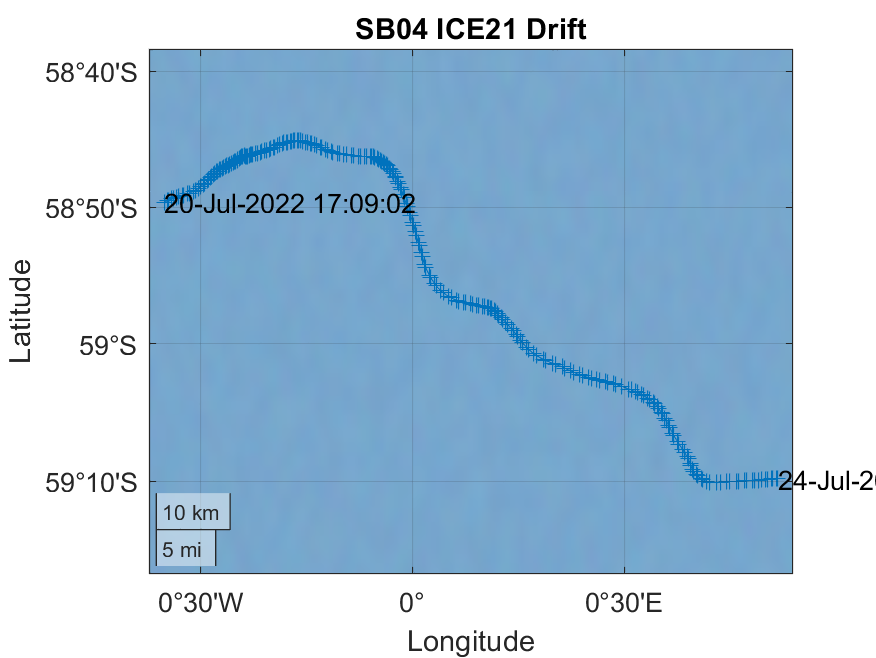

geoplot(SB04.("Latitude"), SB04.("Longitude"), 'Marker', '+')
title("SB04 ICE21 Drift")
text(SB04.("Latitude")(end), SB04.("Longitude")(end), string(SB04.("DateTimeUTC")(end)))
text(SB04.("Latitude")(1), SB04.("Longitude")(1), string(SB04.("DateTimeUTC")(1)))
geobasemap colorterrain
hold off

% geoplot(SB06.("Latitude"), SB06.("Longitude"), 'Marker', '+')
% title("SB06 ICE00 Drift")
% text(SB06.("Latitude")(end), SB06.("Longitude")(end), string(SB06.("DateTimeUTC")(end)))
% text(SB06.("Latitude")(1), SB06.("Longitude")(1), string(SB06.("DateTimeUTC")(1)))
% geobasemap colorterrain

## Plot Individual

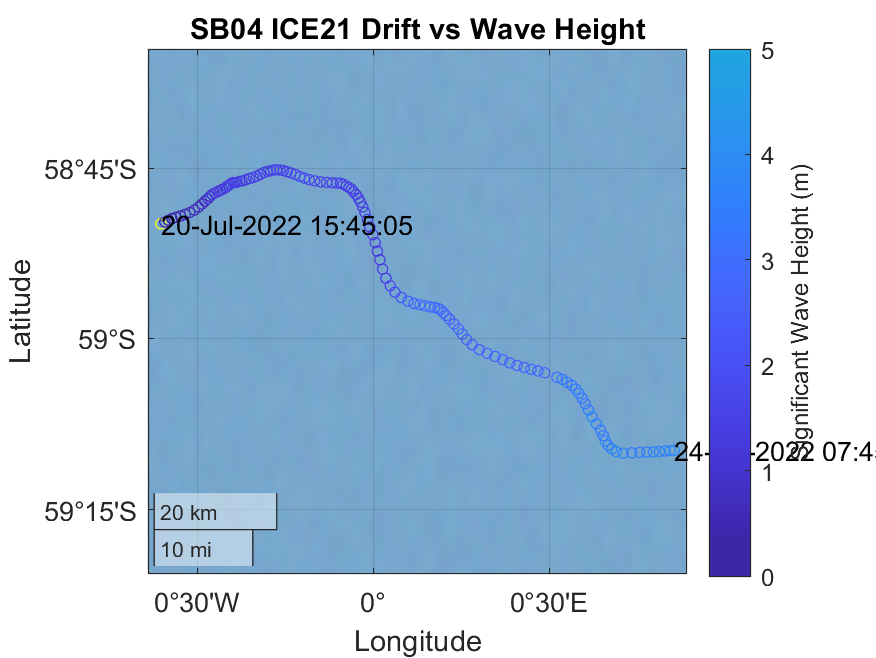

geoscatter(GPSinter(:, 1), GPSinter(:, 2), 15, waveParamSB04.Hm0);
title("SB04 ICE21 Drift vs Wave Height")
text(GPSinter(end, 1), GPSinter(end, 2), string(SB04.("DateTimeUTC")(end)))
text(GPSinter(1, 1), GPSinter(1, 2), string(SB04.("DateTimeUTC")(1)))
geobasemap colorterrain
c = colorbar;
c.Limits = [0 5];
c.Label.String = 'Significant Wave Height (m)';



geoscatter(GPSinter2(:, 1), GPSinter2(:, 2), 15, waveParamSB06.Hm0);

Unrecognized function or variable 'GPSinter2'.

title("SB06 ICE21 Drift vs Wave Height")
text(GPSinter2(end, 1), GPSinter2(end, 2), string(SB06.("DateTimeUTC")(end)))
text(GPSinter2(1, 1), GPSinter2(1, 2), string(SB06.("DateTimeUTC")(1)))
geobasemap colorterrain
c = colorbar;
c.Label.String = 'Significant Wave Height (m)';

## Plot combined

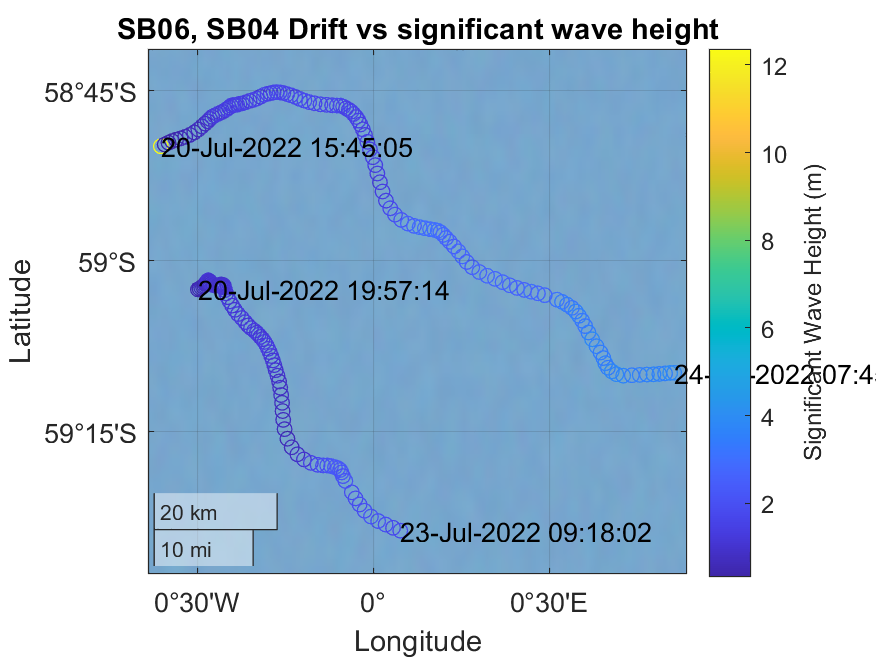

geoscatter(GPSinter(:, 1), GPSinter(:, 2), 30, waveParamSB04.Hm0);
text(GPSinter(end, 1), GPSinter(end, 2), string(SB04.("DateTimeUTC")(end)))
text(GPSinter(1, 1), GPSinter(1, 2), string(SB04.("DateTimeUTC")(1)))
hold on 
geoscatter(GPSinter2(:, 1), GPSinter2(:, 2), 30, waveParamSB06.Hm0);
text(GPSinter2(end, 1), GPSinter2(end, 2), string(SB06.("DateTimeUTC")(end)))
text(GPSinter2(1, 1), GPSinter2(1, 2), string(SB06.("DateTimeUTC")(1)))
hold on
title("SB06, SB04 Drift vs significant wave height")
geobasemap colorterrain
c = colorbar;
c.Label.String = 'Significant Wave Height (m)';
hold off

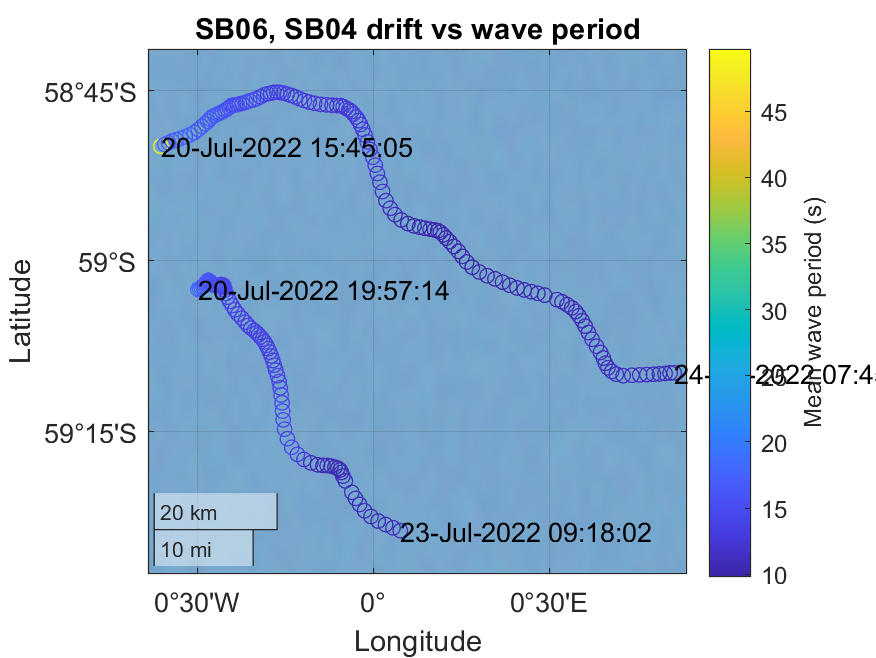



geoscatter(GPSinter(:, 1), GPSinter(:, 2), 30, waveParamSB04.Tm01);
text(GPSinter(end, 1), GPSinter(end, 2), string(SB04.("DateTimeUTC")(end)))
text(GPSinter(1, 1), GPSinter(1, 2), string(SB04.("DateTimeUTC")(1)))
hold on 
geoscatter(GPSinter2(:, 1), GPSinter2(:, 2), 30, waveParamSB06.Tm01);
text(GPSinter2(end, 1), GPSinter2(end, 2), string(SB06.("DateTimeUTC")(end)))
text(GPSinter2(1, 1), GPSinter2(1, 2), string(SB06.("DateTimeUTC")(1)))
hold on
title("SB06, SB04 drift vs wave period")
geobasemap colorterrain
c = colorbar;
c.Label.String = 'Mean wave period (s)';
hold off